%% 0. Initialize Parameters 
n = 1250;                                                       % Number of locations to evaluate bridge failure 
L = 1250;                                                       % Length of bridge 
h = 75;                                                         %Height of cross-section
t = 1.27;                                                       %Thickness of the Matboard
x = linspace(0, L, n);                                          % Define x coordinate 
SFD_PL = zeros(1, n);                                           % Initialize SFD(x) 
b_section = [(80-(2.*t)), t, 10, t, 10, 100];
h_section = [t, (h-t), t, (h-t), t, t];
centroid = [0.635, 36.87, 73.1, 36.87, 73.1, 74.37];
y_top = [t, (h-t), (h-t), (h-t), (h-t), h];
y_bot = [0, 0, ((h-2)*t), 0, ((h-2)*t), (h-t)];
TauU  = 4;
TauG = 2;
E = 4000;
miu = 0.2;
b = 2*t;                                                        
SigT = 30;                                                      % Tensile Strength
SigC = 6;                                                       % Compressive Strength
P = 440;                                                        % Input any arbitrary P value

%Call Functions
[y_bar, I, Q] = Section_Properties (6, b_section, h_section, centroid, y_top, y_bot , 41.7054)

y_bar = 41.7054

I = 4.1573e+05

Q = 6.2492e+03

Q_glue = b_section(end)*h_section(end)*(centroid(end)-y_bar)

Q_glue = 4.1484e+03

[SFD_PL, BMD_PL] = ApplyPL(550, P, x, SFD_PL, n)               % Construct SFD, BMD 

SFD_PL =          0  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981  211.6981


BMD_PL = 	1.0e+05 *

         0    0.0021    0.0042    0.0064    0.0085    0.0106    0.0127    0.0148    0.0169    0.0191    0.0212    0.0233    0.0254    0.0275    0.0296    0.0318    0.0339    0.0360    0.0381    0.0402    0.0423    0.0445    0.0466    0.0487    0.0508    0.0529    0.0550    0.0572    0.0593    0.0614    0.0635    0.0656    0.0677    0.0699    0.0720    0.0741    0.0762    0.0783    0.0804    0.0826    0.0847    0.0868    0.0889    0.0910    0.0931    0.0953    0.0974    0.0995    0.1016    0.1037


[SFD_PL, BMD_PL] = ApplyPL(1249, P, x, SFD_PL, n)               % Construct SFD, BMD 

SFD_PL =          0  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453  133.2453


BMD_PL = 	1.0e+04 *

         0    0.0133    0.0266    0.0400    0.0533    0.0666    0.0799    0.0933    0.1066    0.1199    0.1332    0.1466    0.1599    0.1732    0.1865    0.1999    0.2132    0.2265    0.2398    0.2532    0.2665    0.2798    0.2931    0.3065    0.3198    0.3331    0.3464    0.3598    0.3731    0.3864    0.3997    0.4131    0.4264    0.4397    0.4530    0.4664    0.4797    0.4930    0.5063    0.5197    0.5330    0.5463    0.5596    0.5730    0.5863    0.5996    0.6129    0.6263    0.6396    0.6529


M_MatT_PL = zeros(1, n);
M_MatT_PL = MfailMatT(y_bar, Q, I, SigT, BMD_PL, x, M_MatT_PL, h)

M_MatT_PL = 	1.0e+05 *

         0    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904    2.9904


M_MatC_PL = zeros(1, n);   
M_MatC_PL = MfailMatC(y_bar, Q, I, SigC, BMD_PL, x, M_MatC_PL, h)

M_MatC_PL = 	1.0e+04 *

         0    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918    7.4918


V_fail = Vfail(b, I, Q, TauU)

V_fail = 675.8860

V_fail_glue = Vfail(20, I, Q_glue, TauG)

V_fail_glue = 4.0085e+03

V_Buck = VfailBuck(E, miu,73.73,550,t,I,b,Q, L)

V_Buck = 874.4700


%BUCKLING MOMENT
[M_Buck_flange, P_Buck_flange] = MfailBuck("flange",y_bar,I,E,miu,77.46,BMD_PL, t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_flange = 	1.0e+04 *

         0    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010    4.6010


P_Buck_flange =          0  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583  242.1583


[M_Buck_tip, P_Buck_tip] = MfailBuck("tip",y_bar,I,E,miu,10,BMD_PL, t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_tip = 	1.0e+05 *

         0    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332    2.9332


P_Buck_tip = 	1.0e+03 *

         0    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438    1.5438


[M_Buck_web, P_Buck_web] = MfailBuck("web",y_bar,I,E,miu,75-y_bar-t,BMD_PL, t, L)

M_Buck =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


M_Buck_web = 	1.0e+05 *

         0    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377    4.0377


P_Buck_web = 	1.0e+03 *

         0    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251    2.1251



Pfail = FailLoad(SFD_PL, BMD_PL, V_fail, V_Buck, M_MatT_PL, M_MatC_PL, P_Buck_flange, P_Buck_tip, P_Buck_web)

Pfail = 242.1583

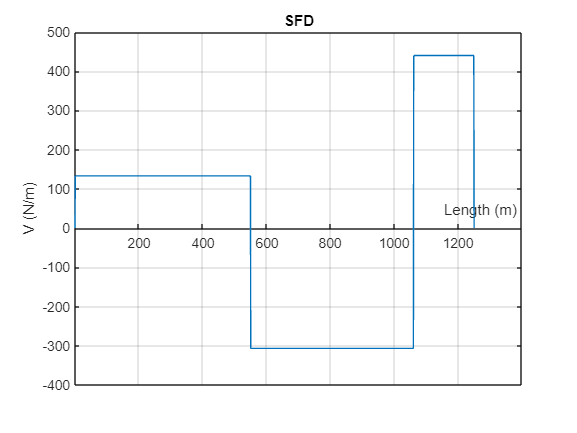

axis =   Axes (BMD) with properties:

             XLim: [0 1400]
             YLim: [-100000 80000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


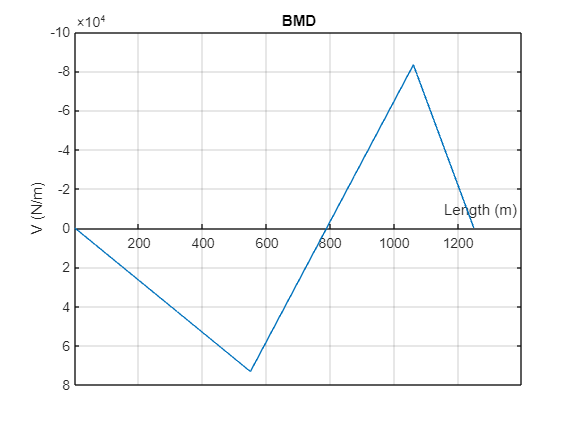

axis =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


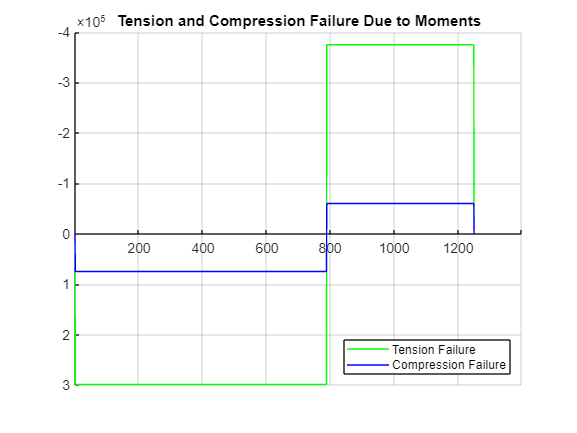

axis =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


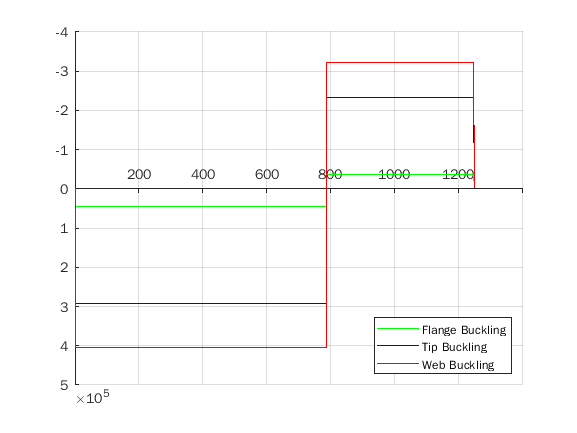


VisualizePL(x, SFD_PL, BMD_PL, M_MatT_PL, M_MatC_PL, M_Buck_flange, M_Buck_tip, M_Buck_web)

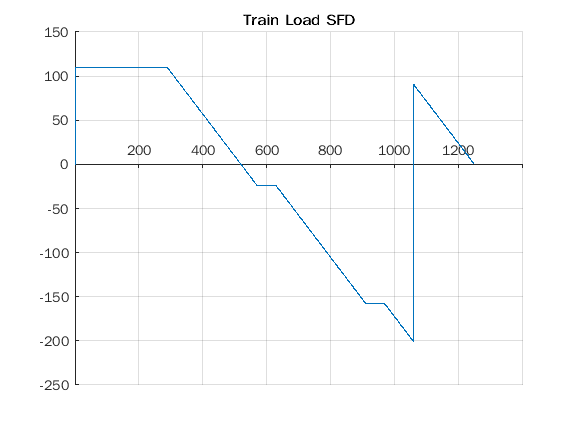

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


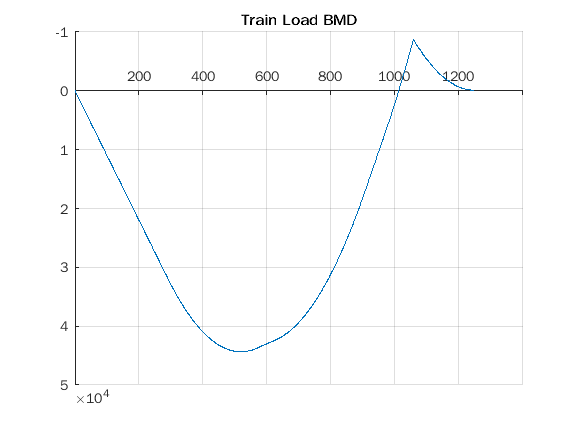

train(n,x)

function [] = VisualizePL(x, SFD_PL, BMD_PL, M_MatT_PL, M_MatC_PL, M_Buck_flange, M_Buck_tip, M_Buck_web)  
% Plots all outputs of design process 

%Plot SFD
figure;
plot(x, SFD_PL)
hold on;
grid on;
axis = gca;
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
title('SFD')
xlabel('Length (m)')
ylabel('V (N/m)')

%Plot BMD
figure;
plot(x, BMD_PL)
hold on;
grid on;
axis = gca;
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
title('BMD')
xlabel('Length (m)')
ylabel('V (N/m)')

%Plot Tenion and Compression Failure due to Moments
figure;
hold on;
grid on;
axis = gca;                                           % To set properties of the axis
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
plot(x, M_MatT_PL, '-g')
plot(x, M_MatC_PL, '-b')
title('Tension and Compression Failure Due to Moments')
legend('Tension Failure', 'Compression Failure')
legend('Location','southeast')
 
figure;
hold on;
grid on;
axis = gca;
axis.YDir = "reverse"
axis.XAxisLocation = 'origin';
axis.YAxisLocation = 'origin';
plot(x, M_Buck_flange, '-g')
plot(x, M_Buck_tip, '-b')
plot(x, M_Buck_web, '-r')
legend('Flange Buckling', 'Tip Buckling', 'Web Buckling')
legend('Location','southeast')
end

function [y_bar, I, Q] = Section_Properties (num, b_series, h_series, y_bot_series, yt_bot_series, yb_bot_series, Q_height)
    for i =  1:num
        A(1,i) = b_series(1,i) * h_series(1,i);                     % Area b*h
        A_ybot(1,i) = A(1,i) * y_bot_series(1,i);                   % Area using y_bot_series
    end

    y_bar = sum(A_ybot)/sum(A);
    for i = 1:num
        I_0(1,i) = (b_series(1,i)*(h_series(1,i)).^3)/12;           % (bh^3)/12
        A_d2(1,i) = A(1,i)* (y_bot_series(1,i)- y_bar).^2;
    end

    I = sum(I_0) + sum(A_d2);
    Q_local = zeros(1,num);                                         % Local Centroid

    for i = 1:num
        if Q_height > yt_bot_series(1,i)
            Q_local(1,i) = A(1,i)*(abs(y_bot_series(1,i) - y_bar));
        elseif (Q_height < yt_bot_series(1,i)) && (Q_height > yb_bot_series(1,i))
            Q_local(1,i) = b_series(1,i) * (Q_height - yb_bot_series(1,i))* (abs((Q_height -yb_bot_series(1,i))/2 - y_bar));
        else
            Q_local(1,i) = 0;
        end
    end
    Q = sum(Q_local);                                               % Gloabl Centorid = Sum of Local Centroids
end

function [ SFD, BMD ] = ApplyPL( xP, P, x, SFD, n ) 
% Constructs SFD and BMD from application of 1 Point Load. Assumes fixed location of supports 
% Input: location and magnitude of point load. The previous SFD can be entered as input to  
%  construct SFD of multiple point loads 
% Output: SFD, BMD both 1-D arrays of length n 
 
    %Locations of supports:
    supp_A = 2;                                                 %Support A
    supp_B = 1060;                                              %Support B

    A_y = P - (xP*P/supp_B);                                    %Reaction Force at support A
    B_y = (xP*P/supp_B);                                        %Reaction Force at support B
    BMD = zeros(1,n);
    
    if xP < supp_B
        for i = supp_A : xP                                     % Support A location to position of point load
            SFD(i) = SFD(i) + A_y;
        end

        for i = xP+1 : supp_B                                   % Position of point load + 1mm to Support B
            SFD(i) = SFD(i) + A_y - P;
        end
        
        for i = supp_B+1 : 1250                                 % Support B to the end of the bridge
            SFD(i) = SFD(i) + A_y - P + B_y;
        end
    end
    
    if xP > supp_B
   
        for i = (supp_A : supp_B)                              % Support A to Support B
            SFD(i) = SFD(i) + A_y;
        end
        
        for i = (supp_B+1 : xP)                                % Support B + 1mm to Position of point load
            SFD(i) = SFD(i) + A_y + B_y;
        end
    
        for i = (xP+1 : 1250)                                  % Point Load + 1mm to the end of the bridge
            SFD(i) = SFD(i) + A_y + B_y - P;
        end
    end
    
    for i = supp_A : 1250
        BMD(i) = BMD(i-1) + SFD(i);
    end
end


function [ V_fail ] = Vfail( b, I, Qcent, TauU ) 
% Calculates shear forces at every value of x that would cause a matboard shear failure 
% Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% Output: V_fail a 1-D array of length n 
 
    V_fail = TauU .* I .* b ./ Qcent;  
end 

function [ V_Buck ] = VfailBuck(E, miu,h,a,t,I,b,Q, L)
% Calculates shear forces at every value of x that would cause a shear buckling failure in the web 
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property) 
% Output: V_Buck a 1-D array of length n 
    for i = 1:L
        TauCr = (5*pi^2 * E)/(12*(1-miu^2))*((t/h)^2 + (t/a)^2);
        V_Buck = TauCr * I * b /Q;
    end

end

%Matboard Moment Faliure due to Tension
function [ M_MatT ] = MfailMatT(y_bar, Q, I, SigT, BMD, x, M_MatT, h)%{Sectional Properties}, SigT, BMD )  
% Calculates bending moments at every value of x that would cause a matboard tension failure 
% Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% Output: M_MatT a 1-D array of length n 
  
    for i = 2 : (length(x)-1)
        if BMD(i) > 0 % If the moment is positive, the tension failure will be at the bottom 
            M_MatT(i) = SigT * I / (y_bar); 
        elseif BMD(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_MatT(i) = -SigT * I / (h - y_bar); 
        end 
    end 
end 

%Matboard Moment Faliure due to Compression (same as M_MatT)
function [ M_MatC ] = MfailMatC(y_bar, Q, I, SigC, BMD, x, M_MatC, h)
    for i = 2 : length(x)-1  
        if BMD(i) > 0 % Compression failure at top if M is -ve 
            M_MatC(i) = SigC * I / (h - y_bar); 
        elseif BMD(i) < 0 % Compression failure at bottom if M is -ve
            M_MatC(i) = -SigC * I / (y_bar);
        end 
    end 
end

function [ M_Buck, PBuck ] = MfailBuck(part,y_bar,I,E,miu,b,BMD, t, L)
% Calculates bending moments at every value of x that would cause a buckling failure 
% Input: Sectional Properties (list of 1-D arrays), E, mu (material property), BMD (1-D array) 
% Output: M_MatBuck a 1-D array of length n 
    M_Buck = zeros(1,L)

    if part == "tip"
        SigCr = ((0.425*pi^2 * E)/(12*(1-miu^2)))*((t/b)^2);
    elseif part  == "flange"
        SigCr = ((4*(pi^2) * E)/(12*(1-miu^2)))*((t/b)^2);
    elseif part == "web"
        SigCr = ((6*pi^2 * E)/(12*(1-miu^2)))*((t/b)^2);
    end

    for i = 1:(L-1)
        if BMD(i) > 0                                   % Positive Moment
            M_Buck(i) = SigCr * I/(75 - y_bar);
            PBuck = M_Buck./166;
        end
        if BMD(i) < 0                                   % Negative Moment
            M_Buck(i) = -SigCr * I/y_bar;
            PBuck = M_Buck./190;
        end
    end
end

function [ Pfail ] = FailLoad(SFD_PL, BMD_PL, V_fail, V_Buck, M_MatT_PL, M_MatC_PL, P_Buck_flange, P_Buck_tip, P_Buck_web)
    max_SFD_PL = max(abs(SFD_PL));
    max_BMD_PL = max(abs(BMD_PL));
    max_V_fail = max(abs(V_fail));
    max_V_Buck = max(abs(V_Buck));
    max_M_MatT_PL = max(abs(M_MatT_PL));
    max_M_MatC_PL = max(abs(M_MatC_PL));
    max_P_Buck_flange = max(abs(P_Buck_flange));
    max_P_Buck_tip = max(abs(P_Buck_tip));
    max_P_Buck_web = max(abs(P_Buck_web));
    minLoads = [max_SFD_PL, max_BMD_PL, max_V_fail, max_V_Buck, max_M_MatT_PL, max_M_MatC_PL, max_P_Buck_flange, max_P_Buck_tip, max_P_Buck_web];
    Pfail = min(minLoads);
end 

function [] = train(n, x)

    SFD_long = NaN(1, 1250, 2210);
    BMD_long = NaN(1, 1250, 2210);
    for j = 1:2210

        SFD_PL = zeros(1, n);      % Initialize SFD(x)
        train_start = j;

        for j = (train_start:train_start + 280)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        for j = (train_start + 340:train_start + 620)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        for j = (train_start + 680:train_start + 960)
            start = j - 960;
            if (start>=1 & start<=1250)
                [SFD_PL, BMD_PL] = ApplyPL(start, 0.4761, x, SFD_PL, n);
            end
        end

        SFD_long(1, :, j) = SFD_PL(:);
        BMD_long(1, :, j) = BMD_PL(:);
    end

    figure;
    hold on;
    grid on;
    ax = gca;
    ax.XAxisLocation = 'origin';
    title('Train Load SFD')
    plot(x, SFD_long(1, :, 2210))

    figure;
    hold on;
    grid on;
    ax = gca;
    ax.YDir = "reverse"
    ax.XAxisLocation = 'origin';
    title('Train Load BMD')
    plot(x, BMD_long(1, :, 2210))
end